%%INPUTS
run AircraftData.mlx;

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


%Flight Conditions
h = 25000 %ft

h = 25000

V = 375; %kts
[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
AirDens = DensRat*2.3769*10^-3

AirDens = 0.0011

V=V*1.688

V = 633

AoA = 0;

%Wing Parameters
QuarterSweep = Vanguard.Wing.QuarterChordSweep %deg

QuarterSweep = 0

Df = Vanguard.Fuselage.Diameter;
TaperRatio = Vanguard.Wing.TaperRatio;
S = Vanguard.Wing.S;
b = Vanguard.Wing.b;
AR = Vanguard.Wing.AR;
SweepLE = atand(tand(QuarterSweep)-4/AR*((0-0.25)*(1-TaperRatio)/(1+TaperRatio)))

SweepLE = 2.7814

InstallAngle = 1.72

InstallAngle = 1.7200

LiftCurveSlope = 0.0876 %Per deg

LiftCurveSlope = 0.0876

Yehudi = Vanguard.Wing.Yehudi;
Cr = Vanguard.Wing.Cr

Cr = 16.6852


%Prop Parameters
ThrustAngle = 0

ThrustAngle = 0

Rp = 10

Rp = 10

%HP = 18698*2 %Per engine
PropEff = 0.81

PropEff = 0.8100

zProp = 4

zProp = 4


%Thrust = HP*0.81/V*550
Thrust = 12000*2

Thrust = 24000


x1 = 20.5

x1 = 20.5000

x2 = 42.5

x2 = 42.5000


ThrustCoef = Thrust/(0.5*AirDens*V^2*S) 

ThrustCoef = 0.0713

PropCorrelationParam = S*ThrustCoef/(8*Rp^2) %Use to find f

PropCorrelationParam = 0.1407

Sp = pi*Rp^2

Sp = 314.1593


%DATCOM Figures
PropNormForceCoeff = 0.5 %Pg 1387 Depends on Nominal Blade Anlgle and # of props

PropNormForceCoeff = 0.5000

PropUpwashGradient = 0.4 %Pg 1275 Depends on AR and Prop Distance from 0.25Cr

PropUpwashGradient = 0.4000

f = 1.5 %Pg 1387 Depends on PropCorrelationParam

f = 1.5000

C1 = 0.3 %Pg 1388 Depends on PropCorrelationParam

C1 = 0.3000

C2 = 0.2 %Pg 1388 Depends on PropCorrelationParam

C2 = 0.2000

K = 1 %Pg 1398 Depends on Si/S

K = 1

K1 = 0.8 %Pg 1389 Depends on Prop CorrelationParam, AR, AR immersed

K1 = 0.8000

K2 = 0.8 %Pg 1389 Depends on Prop CorrelationParam, AR, AR immersed

K2 = 0.8000


%For clean wing
daCLmax = 1.2

daCLmax = 1.2000

MaxLiftCoefRatio = 0.9

MaxLiftCoefRatio = 0.9000


%Airfoil Parameters
ZeroLiftAngle = Vanguard.Wing.Airfoil.ZeroLiftAngle;
ClMax = Vanguard.Wing.Airfoil.Clmax;
AirfoilStallAngle = Vanguard.Wing.Airfoil.StallAngle;
Cla = Vanguard.Wing.Airfoil.Cla;


%Clean wing
CLMax = MaxLiftCoefRatio*ClMax

CLMax = 1.4400

WingStallAngle = CLMax/LiftCurveSlope+ZeroLiftAngle+daCLmax

WingStallAngle = 14.6384


%Flapped From Graphs
FlapDeflec = 40 %Deg

FlapDeflec = 40

ddZeroLiftAngle = -0.45 %For Slotted flaps with cf/c = 0.3 at 40deg deflection

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = ddZeroLiftAngle*FlapDeflec

dZeroLiftAngle = -18


%%CALCULATIONS

%Flapped Wing
y1flap=Df/2

y1flap = 7.9165

y2flap=0.75*b/2

y2flap = 44.2500

y3flap=0

y3flap = 0

y4flap=0

y4flap = 0


y3Aileron = 56.05

y3Aileron = 56.0500


cr = 2*S/(b*(1+TaperRatio))

cr = 19.1092


c1flap = YehudiChord(y1flap)

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


c1flap = 16.6852

c2flap = YehudiChord(y2flap)

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


c2flap = 10.4603

c3flap = YehudiChord(y3flap)

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


c3flap = 16.6852

c4flap = YehudiChord(y4flap)

Vanguard = struct with fields:
           MTOW: 147661
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147661
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


c4flap = 16.6852


c3Aileron = cr*(1-(1-TaperRatio)*2*y3Aileron/b)

c3Aileron = 8.2169


if y1flap>=Yehudi
    SWF = 2*((c1flap+c2flap)/2*(y2flap-y1flap) + (c3flap+c4flap)/2*(y4flap-y3flap))
else
    SWF = 2*(c1flap*(Yehudi-y1flap)+(c1flap+c2flap)/2*(y2flap-Yehudi) + (c3flap+c4flap)/2*(y4flap-y3flap))
end

SWF = 1.0615e+03



    SweepFactor = (1-0.08*(cosd(QuarterSweep))^2)*(cosd(QuarterSweep))^(3/4)

SweepFactor = 0.9200


dAirfoilStallAngle = -4*10^(-7)*FlapDeflec^4+3*10^(-5)*FlapDeflec^3-0.0019*FlapDeflec^2-0.024*FlapDeflec

dAirfoilStallAngle = -3.1040


AirfoilStallAngleFlapped = AirfoilStallAngle + dAirfoilStallAngle

AirfoilStallAngleFlapped = 12.8960


ZeroLiftAngleFlapped = ZeroLiftAngle + dZeroLiftAngle

ZeroLiftAngleFlapped = -21


ClMaxFlapped = Cla*(AirfoilStallAngleFlapped - ZeroLiftAngleFlapped-daCLmax)

ClMaxFlapped = 3.5855


dClMaxFlapped = ClMaxFlapped - ClMax

dClMaxFlapped = 1.9855

dCLMaxFlapped = dClMaxFlapped*SWF*SweepFactor/S

dCLMaxFlapped = 1.2285


CLMaxFlapped = CLMax + dCLMaxFlapped

CLMaxFlapped = 2.6685


%Powered CLmax



%KN =
KN = 80.7 %ASSUMED

KN = 80.7000


TruePropNormalForceCoeff = PropNormForceCoeff*(1+0.8*(KN/80.7-1))

TruePropNormalForceCoeff = 0.5000


PropPlaneAngle = ThrustAngle + PropUpwashGradient*(AoA+InstallAngle-ZeroLiftAngle)  

PropPlaneAngle = 1.8880


dCLPropNorm = f*TruePropNormalForceCoeff*PropPlaneAngle/57.3*Sp/S*cosd(ThrustAngle)

dCLPropNorm = 0.0049


UpwashGradient = C1 + C2*TruePropNormalForceCoeff

UpwashGradient = 0.4000


PropDownwashAngle = UpwashGradient*PropPlaneAngle

PropDownwashAngle = 0.7552


dWingAoA = -PropDownwashAngle/(1+PropUpwashGradient)

dWingAoA = -0.5394


PropUpwashAngle = PropUpwashGradient*(AoA+InstallAngle-ZeroLiftAngle)

PropUpwashAngle = 1.8880


for x=1:1:27
   
    CL = (x-1)/10
    
    %Inboard Props
    y1 = 19 %ft to centerline of prop
    z1 = x1*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing
    b1 = 2*sqrt(Rp^2-z1^2)
    c1 = cr*(1-(1-TaperRatio)*2*y1/b)
    S1 = b1*c1
    AReff1 = b1/c1
    dSlipstreamDynPressure1 = S*ThrustCoef/(pi*Rp^2)
    dCLWash1 = (1+dSlipstreamDynPressure1)*S1/S*LiftCurveSlope*dWingAoA*K1
    dCLq1 = K1*dSlipstreamDynPressure1*S1/S*CL
    
    %Outboard Props
    y2 = 45.5 %ft to centerline of prop
    z2 = x2*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing
    b2 = 2*sqrt(Rp^2-z2^2)
    c2 = cr*(1-(1-TaperRatio)*2*y2/b)
    S2 = b2*c2
    AReff2 = b2/c2
    dSlipstreamDynPressure2 = S*ThrustCoef/(pi*Rp^2)
    dCLWash2 = (1+dSlipstreamDynPressure2)*S2/S*LiftCurveSlope*dWingAoA*K1
    dCLq2 = K2*dSlipstreamDynPressure2*S2/S*CL
    
    ImmersedRatio = (2*S1+2*S2)/S
    
    CLPowered(x) = CL + K*(4*dCLPropNorm + 2*dCLWash1 + 2*dCLq1 + 2*dCLWash2 + 2*dCLq2)

    alpha(x) = (CL/LiftCurveSlope)+ZeroLiftAngleFlapped
    
end

CL = 0

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0

ImmersedRatio = 0.5784

CLPowered = -0.0100

alpha = -21

CL = 0.1000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.0050

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0033

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066


alpha =   -21.0000  -19.8584


CL = 0.2000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.0101

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0065

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231


alpha =   -21.0000  -19.8584  -18.7169


CL = 0.3000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.0151

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0098

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397


alpha =   -21.0000  -19.8584  -18.7169  -17.5753


CL = 0.4000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.0201

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0131

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338


CL = 0.5000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.0251

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0163

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922


CL = 0.6000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.0302

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0196

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507


CL = 0.7000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.0352

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0228

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091


CL = 0.8000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.0402

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0261

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061    0.9226


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091  -11.8676


CL = 0.9000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.0453

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0294

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061    0.9226    1.0392


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091  -11.8676  -10.7260


CL = 1

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.0503

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0326

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061    0.9226    1.0392    1.1558


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091  -11.8676  -10.7260   -9.5845


CL = 1.1000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.0553

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0359

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061    0.9226    1.0392    1.1558    1.2724


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091  -11.8676  -10.7260   -9.5845   -8.4429


CL = 1.2000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.0603

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0392

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061    0.9226    1.0392    1.1558    1.2724    1.3890


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091  -11.8676  -10.7260   -9.5845   -8.4429   -7.3014


CL = 1.3000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.0654

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0424

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061    0.9226    1.0392    1.1558    1.2724    1.3890    1.5056


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091  -11.8676  -10.7260   -9.5845   -8.4429   -7.3014   -6.1598


CL = 1.4000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.0704

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0457

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061    0.9226    1.0392    1.1558    1.2724    1.3890    1.5056    1.6221


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091  -11.8676  -10.7260   -9.5845   -8.4429   -7.3014   -6.1598   -5.0183


CL = 1.5000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.0754

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0490

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061    0.9226    1.0392    1.1558    1.2724    1.3890    1.5056    1.6221    1.7387


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091  -11.8676  -10.7260   -9.5845   -8.4429   -7.3014   -6.1598   -5.0183   -3.8767


CL = 1.6000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.0804

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0522

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061    0.9226    1.0392    1.1558    1.2724    1.3890    1.5056    1.6221    1.7387    1.8553


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091  -11.8676  -10.7260   -9.5845   -8.4429   -7.3014   -6.1598   -5.0183   -3.8767   -2.7352


CL = 1.7000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.0855

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0555

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061    0.9226    1.0392    1.1558    1.2724    1.3890    1.5056    1.6221    1.7387    1.8553    1.9719


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091  -11.8676  -10.7260   -9.5845   -8.4429   -7.3014   -6.1598   -5.0183   -3.8767   -2.7352   -1.5936


CL = 1.8000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.0905

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0588

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061    0.9226    1.0392    1.1558    1.2724    1.3890    1.5056    1.6221    1.7387    1.8553    1.9719    2.0885


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091  -11.8676  -10.7260   -9.5845   -8.4429   -7.3014   -6.1598   -5.0183   -3.8767   -2.7352   -1.5936   -0.4521


CL = 1.9000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.0955

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0620

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061    0.9226    1.0392    1.1558    1.2724    1.3890    1.5056    1.6221    1.7387    1.8553    1.9719    2.0885    2.2051


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091  -11.8676  -10.7260   -9.5845   -8.4429   -7.3014   -6.1598   -5.0183   -3.8767   -2.7352   -1.5936   -0.4521    0.6895


CL = 2

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.1006

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0653

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061    0.9226    1.0392    1.1558    1.2724    1.3890    1.5056    1.6221    1.7387    1.8553    1.9719    2.0885    2.2051    2.3217


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091  -11.8676  -10.7260   -9.5845   -8.4429   -7.3014   -6.1598   -5.0183   -3.8767   -2.7352   -1.5936   -0.4521    0.6895    1.8311


CL = 2.1000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.1056

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0685

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061    0.9226    1.0392    1.1558    1.2724    1.3890    1.5056    1.6221    1.7387    1.8553    1.9719    2.0885    2.2051    2.3217    2.4382


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091  -11.8676  -10.7260   -9.5845   -8.4429   -7.3014   -6.1598   -5.0183   -3.8767   -2.7352   -1.5936   -0.4521    0.6895    1.8311    2.9726


CL = 2.2000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.1106

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0718

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061    0.9226    1.0392    1.1558    1.2724    1.3890    1.5056    1.6221    1.7387    1.8553    1.9719    2.0885    2.2051    2.3217    2.4382    2.5548


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091  -11.8676  -10.7260   -9.5845   -8.4429   -7.3014   -6.1598   -5.0183   -3.8767   -2.7352   -1.5936   -0.4521    0.6895    1.8311    2.9726    4.1142


CL = 2.3000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.1156

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0751

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061    0.9226    1.0392    1.1558    1.2724    1.3890    1.5056    1.6221    1.7387    1.8553    1.9719    2.0885    2.2051    2.3217    2.4382    2.5548    2.6714


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091  -11.8676  -10.7260   -9.5845   -8.4429   -7.3014   -6.1598   -5.0183   -3.8767   -2.7352   -1.5936   -0.4521    0.6895    1.8311    2.9726    4.1142    5.2557


CL = 2.4000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.1207

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0783

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061    0.9226    1.0392    1.1558    1.2724    1.3890    1.5056    1.6221    1.7387    1.8553    1.9719    2.0885    2.2051    2.3217    2.4382    2.5548    2.6714    2.7880


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091  -11.8676  -10.7260   -9.5845   -8.4429   -7.3014   -6.1598   -5.0183   -3.8767   -2.7352   -1.5936   -0.4521    0.6895    1.8311    2.9726    4.1142    5.2557    6.3973


CL = 2.5000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.1257

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0816

ImmersedRatio = 0.5784

CLPowered =    -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061    0.9226    1.0392    1.1558    1.2724    1.3890    1.5056    1.6221    1.7387    1.8553    1.9719    2.0885    2.2051    2.3217    2.4382    2.5548    2.6714    2.7880    2.9046


alpha =   -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091  -11.8676  -10.7260   -9.5845   -8.4429   -7.3014   -6.1598   -5.0183   -3.8767   -2.7352   -1.5936   -0.4521    0.6895    1.8311    2.9726    4.1142    5.2557    6.3973    7.5388


CL = 2.6000

y1 = 19

z1 = 4.4054

b1 = 17.9547

c1 = 15.4169

S1 = 276.8057

AReff1 = 1.1646

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = -0.0090

dCLq1 = 0.1307

y2 = 45.5000

z2 = 4.8404

b2 = 17.5009

c2 = 10.2671

S2 = 179.6845

AReff2 = 1.7046

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = -0.0058

dCLq2 = 0.0849

ImmersedRatio = 0.5784

CLPowered = 1×27
   -0.0100    0.1066    0.2231    0.3397    0.4563    0.5729    0.6895    0.8061    0.9226    1.0392    1.1558    1.2724    1.3890    1.5056    1.6221    1.7387    1.8553    1.9719    2.0885    2.2051    2.3217    2.4382    2.5548    2.6714    2.7880    2.9046    3.0212


alpha = 1×27
  -21.0000  -19.8584  -18.7169  -17.5753  -16.4338  -15.2922  -14.1507  -13.0091  -11.8676  -10.7260   -9.5845   -8.4429   -7.3014   -6.1598   -5.0183   -3.8767   -2.7352   -1.5936   -0.4521    0.6895    1.8311    2.9726    4.1142    5.2557    6.3973    7.5388    8.6804


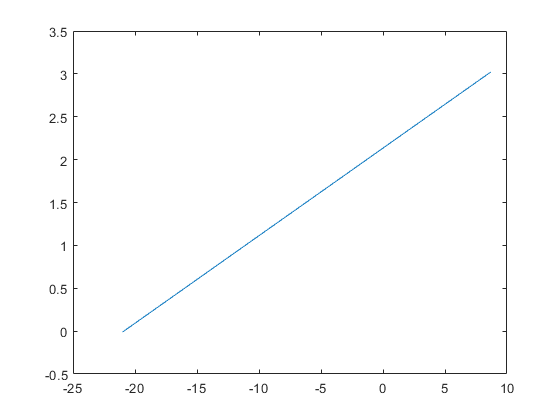


plot(alpha,CLPowered)


%Inboard Props
y1 = 19 %ft to centerline of prop

y1 = 19

z1 = x1*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing

z1 = 4.4054

b1 = 2*sqrt(Rp^2-z1^2)

b1 = 17.9547

c1 = cr*(1-(1-TaperRatio)*2*y1/b)

c1 = 15.4169

S1 = b1*c1

S1 = 276.8057

AReff1 = b1/c1

AReff1 = 1.1646

dSlipstreamDynPressure1 = S*ThrustCoef/(pi*Rp^2)

dSlipstreamDynPressure1 = 0.3584

dCLWash1 = (1+dSlipstreamDynPressure1)*S1/S*LiftCurveSlope*dWingAoA*K1

dCLWash1 = -0.0090

dCLq1 = K1*dSlipstreamDynPressure1*S1/S*CLMaxFlapped

dCLq1 = 0.1342


%Outboard Props
y2 = 45.5 %ft to centerline of prop

y2 = 45.5000

z2 = x2*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing

z2 = 4.8404

b2 = 2*sqrt(Rp^2-z2^2)

b2 = 17.5009

c2 = cr*(1-(1-TaperRatio)*2*y2/b)

c2 = 10.2671

S2 = b2*c2

S2 = 179.6845

AReff2 = b2/c2

AReff2 = 1.7046

dSlipstreamDynPressure2 = S*ThrustCoef/(pi*Rp^2)

dSlipstreamDynPressure2 = 0.3584

dCLWash2 = (1+dSlipstreamDynPressure2)*S2/S*LiftCurveSlope*dWingAoA*K1

dCLWash2 = -0.0058

dCLq2 = K2*dSlipstreamDynPressure2*S2/S*CLMaxFlapped

dCLq2 = 0.0871


ImmersedRatio = (2*S1+2*S2)/S

ImmersedRatio = 0.5784


CLMaxPowered = CLMaxFlapped + K*(4*dCLPropNorm + 2*dCLWash1 + 2*dCLq1 + 2*dCLWash2 + 2*dCLq2)

CLMaxPowered = 3.1010